# 实验一： 计算机控制系统性能分析

考虑如图1所示的计算机控制系统

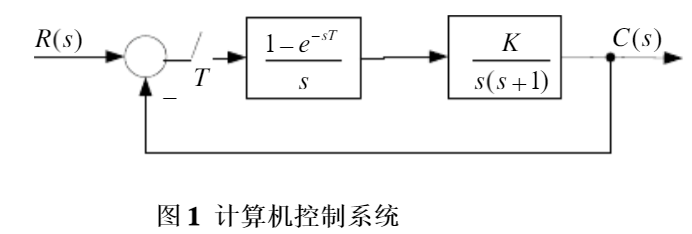

## 系统稳定性分析

### 离散系统稳定性，讨论令系统稳定的K的取值范围

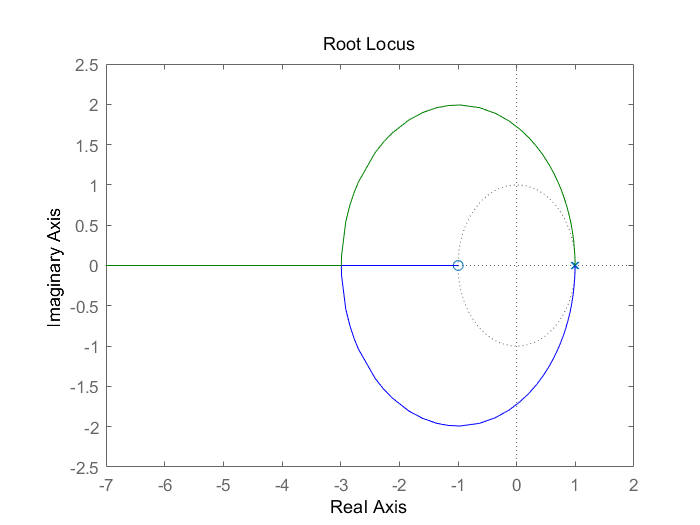

%增益为1的开环传递函数
num=1;
den=conv([1 0],[1 1]);
sysc=tf(num,den);
%ZOH离散化
sysd=c2d(sysc,0.01,'zoh');
%绘制根轨迹图
rlocus(sysd)

使用rlocfind(sysd2)可以寻找到令系统稳定的K的取值范围为:0<K<2.36(T=0.01)。

### 离散系统稳定性，讨论令系统稳定的K的取值范围。

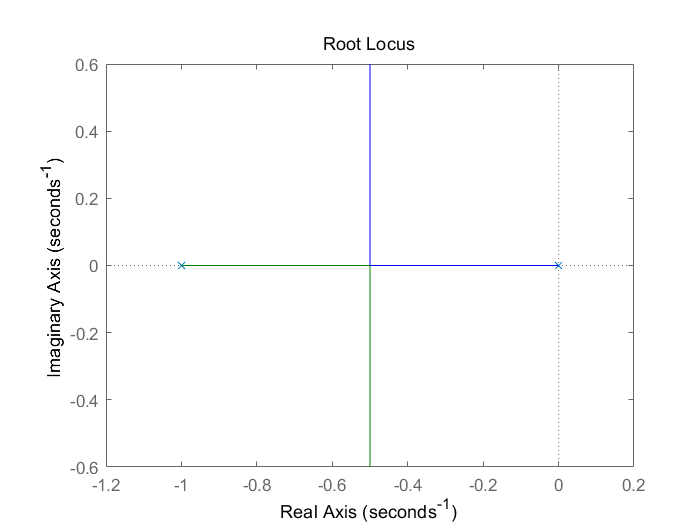

rlocus(sysc)

## 时域特性分析

### 连续系统阶跃响应信号

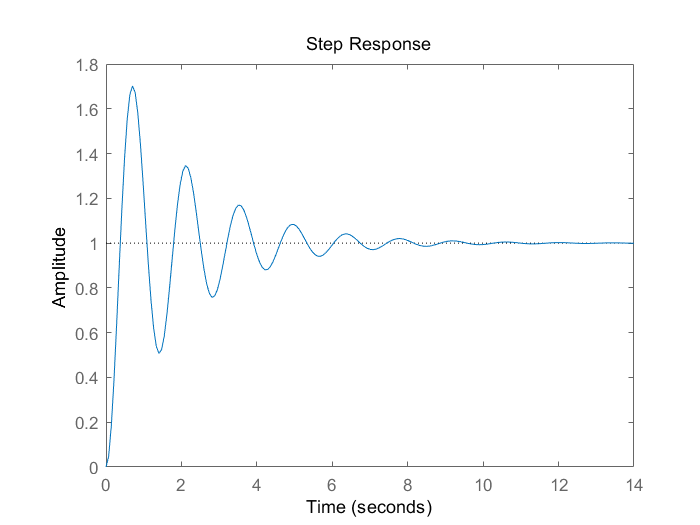

K=20;
Phic=feedback(K*sysc,1);
stepplot(Phic);

infoc=stepinfo(Phic)

infoc = 包含以下字段的 struct :
        RiseTime: 0.2545
    SettlingTime: 7.8152
     SettlingMin: 0.5072
     SettlingMax: 1.7021
       Overshoot: 70.2118
      Undershoot: 0
            Peak: 1.7021
        PeakTime: 0.7025


### 离散化系统稳定性，讨论令系统稳定的K的取值范围

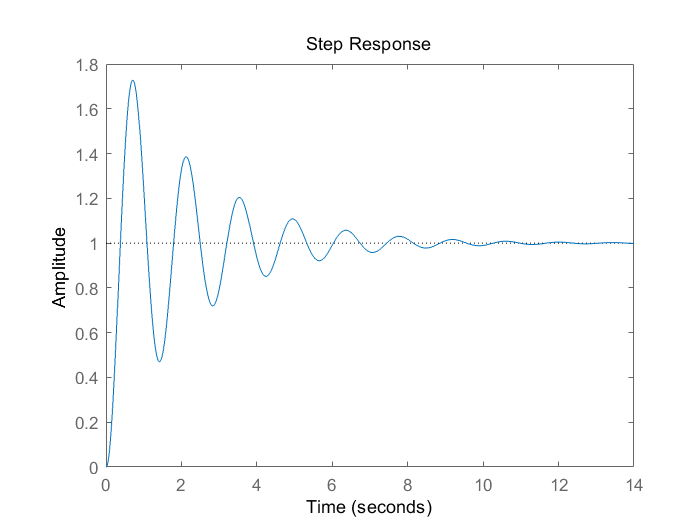

Phid=feedback(K*sysd,1);
step(Phid);

infod=stepinfo(Phid)

infod = 包含以下字段的 struct :
        RiseTime: 0.2400
    SettlingTime: 8.5800
     SettlingMin: 0.4703
     SettlingMax: 1.7277
       Overshoot: 72.7728
      Undershoot: 0
            Peak: 1.7277
        PeakTime: 0.7100


%%两者的比较
infoc,infod

infoc = 包含以下字段的 struct :
        RiseTime: 0.2545
    SettlingTime: 7.8152
     SettlingMin: 0.5072
     SettlingMax: 1.7021
       Overshoot: 70.2118
      Undershoot: 0
            Peak: 1.7021
        PeakTime: 0.7025


infod = 包含以下字段的 struct :
        RiseTime: 0.2400
    SettlingTime: 8.5800
     SettlingMin: 0.4703
     SettlingMax: 1.7277
       Overshoot: 72.7728
      Undershoot: 0
            Peak: 1.7277
        PeakTime: 0.7100


## 频域特性

### 连续开环传递函数的波特图

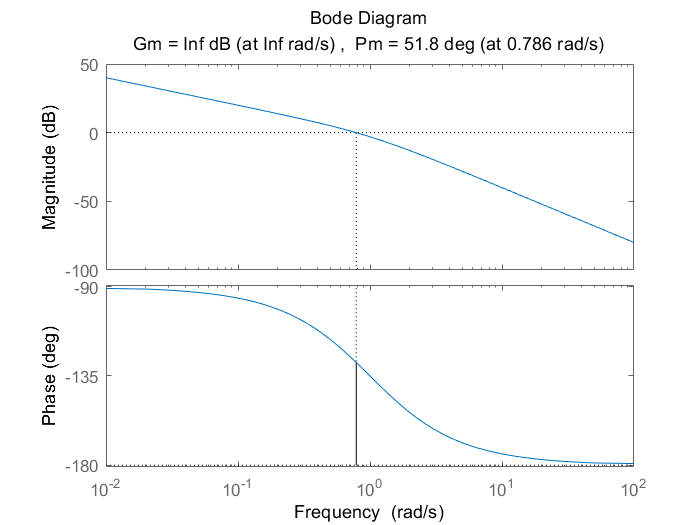

margin(sysc)

### 离散化开环传递函数的波特图

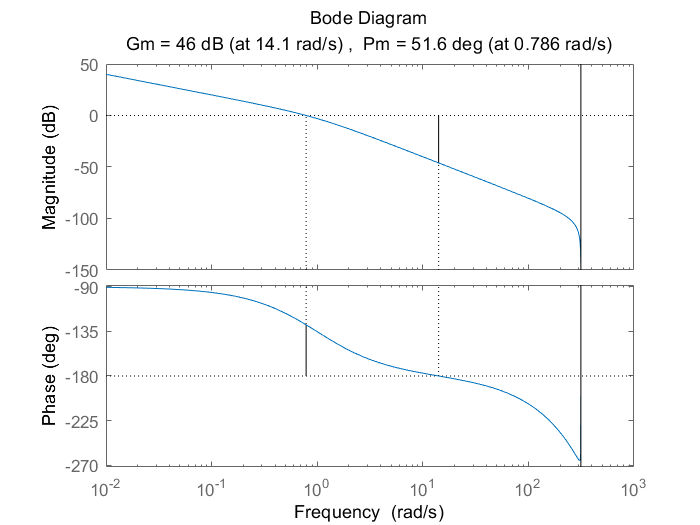

margin(sysd)

离散系统在特定频率上画波特图

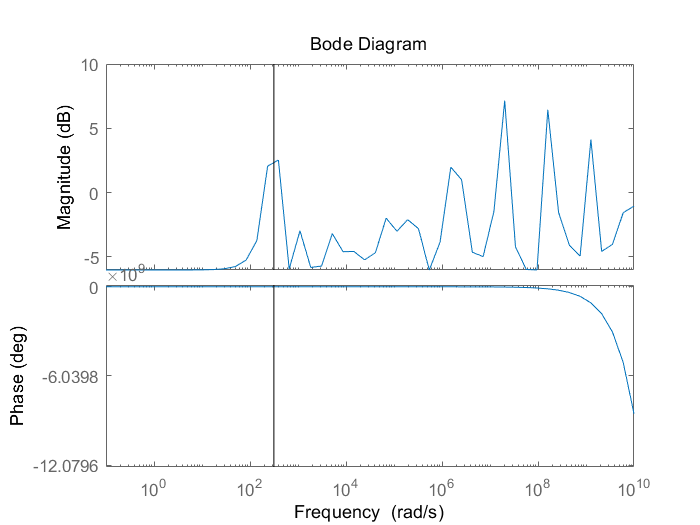

[num,den]=tfdata(sysc);
w=logspace(-1,10);
dbode(num,den,0.01,w)

连续系统和离散化系统(不指定频率分量）的结果比较

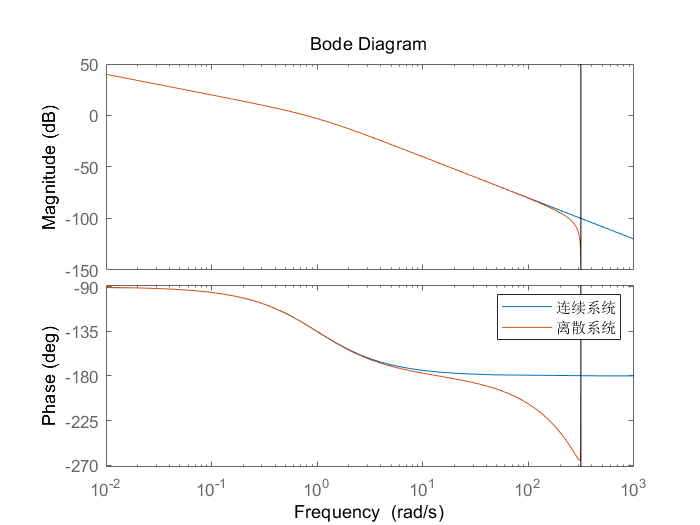

figure()
hold on 
bode(sysc)
bode(sysd)
hold off
legend(["连续系统","离散系统"],"Location","northeast")

连续系统与离散系统（指定频率分量）比较

[百度文库中的参考报告](https://wenku.baidu.com/view/49da289e06a1b0717fd5360cba1aa81144318fc6.html)中指定了w进行比较的,其中认为

- 频率特性是w的周期函数，当wT沿着单位圆每转一周时，频率特性周期性重复一次，这是连续系统没有的。 

- 幅频特性是w的偶函数，相频特性是w的奇函数，连续系统也有这个特性。 

- 离散环节频率特性形状与连续系统频率特性形状有较大差别，特别是当采样周期较大以及频率较高时，由于混叠，使频率特性形状有较大变化，主要表现有: 高频时会出现多个峰值； 可能出现正相位； 仅在较小的采样周期或低频段与连续系统频率特性相接近。 

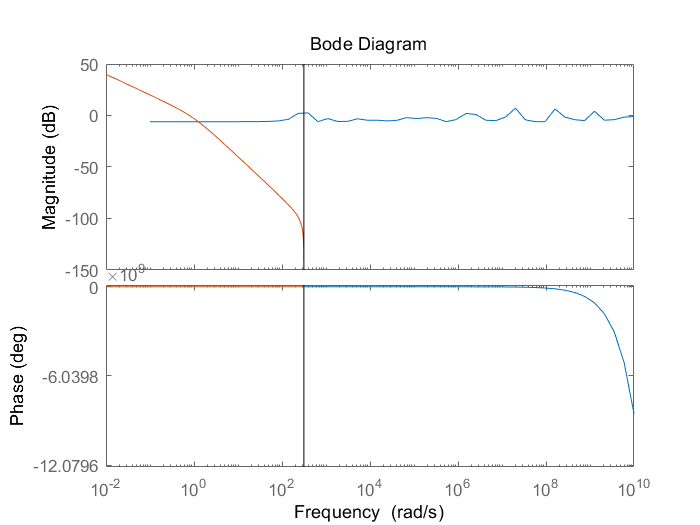

figure()
[num,den]=tfdata(sysc);
w=logspace(-1,10);
hold on
dbode(num,den,0.01,w)
bode(sysd)
hold off